# **Lab 2:  Spectral analysis and Detection theory**

**Statistical Signal Processing (5CTA0) - Lab Assignment**

Lecturers: Simona Turco (Flux 7.076), Franz Lampel (Flux 7.064)

Assistants: Yizhou Huang, Ben Luijten, Agata Barbagini, Xueting Li

**Students (Name + IDs):**

**Group #: **

## General info and guidelines

To complete and submit the Labs:

`•`All students must register on Canvas.

`•`Each lab will be carried out in groups of 4 students, which must register on Canvas.

`•`All information and data will be available on Canvas.

`•`Each group must carry out all assignments of the Lab and hand in a report for each Lab.

`•`**The report is obtained by exporting this matlab live script as pdf. This is the only file that you need to provide.**

`•`**Sometimes, runing the code within livescript might be slow. You may consider to first implment and test your code in a seperate .m file, and copy the code to livescript in the end. **

`•`The report must be submitted through Canvas.

`•`In case of problems, the labs can alternatively be submitted by emailing the lab assistants. The email address are available on Canvas.

`•`The report must be accompanied by the peer-review form, which is used to provide an indication of the contribution of each student in the group. The link to the peer review form is available on Canvas.

`•`If plagiarism is detected, the Lab will be judged with 0 points.

Below, some useful tips for working with MATLAB and for producing a neat Lab report:

`•`Make use of comments to divide the code in sections and facilitate its understanding.

`•`Use the command `doc or` `help` to learn how to use a specific MATLAB functions (e.g.`doc stem`).

`•`Make sure that all your graphs are easily readable, even when printed in black and white. Use for this purpose the options of the plot/stem function to properly increase the dimension and/or change the marker symbols, for example:

`•`Make sure that all your graphs have their axes properly labeled and a legend when several signals are plotted on the same graph. Also, make sure that all the text is readable. Below some useful commandsfor these purposes:

## Credits and deadlines

Each Lab counts for 15% of the final grade, for a total of 30%. The remaining 70% is determined by the final written exam. 

Please submit this lab on Canvas by 30/10/22 at 23:59.

## Assignment 1: Noise and spectral estimation 

Speech signals are one dimensional function of time, representing the changing in the air pressure. It is considered a stochastic signal (non-deterministic), because it is not periodic, and from the observation of *N* samples, it is impossible to predict the value of the next *(N+1*th) sample.

### Noise

Very often speech and in general audio signals are corrupted by noise. 

The Signal-to-Noise ratio (SNR) is an important parameter to define how much the signal is corrupted by noise. In the case of a stochastic signal, corrupted by additive random noise, SNR is defined as the ratio between signal and noise power. 


$${SNR}_{\left\lbrack dB\right\rbrack } =20∙\log_{10} \frac{P_{s\textrm{ignal}} }{P_{noise} }=\ 20∙\log_{10} \frac{{\left.{\left(\sigma \right.}_{s\textrm{ignal}} \right)}^2 }{{\left.{\left(\sigma \right.}_{noise} \right)}^2 }\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(1\right)$$


Where $\sigma_{\;\textrm{signal}}$ and $\sigma {\;}_{\textrm{noise}}$ are the standard deviation of the signal and of the additive noise, respectively. 

Depending on its spectrum, the noise can be classified as white or coloured. 

The white Gaussian noise is an array of random variables with Gaussian distribution whose spectrum uniformly covers all frequencies. 

Coloured noise will have different integrated power at different frequency bands. The most common coloured noises are: 

- Pink Gaussian noise: Arrays of random variables with Gaussian distribution, in which the low-frequency components have higher power.

- Blue Gaussian noise: Arrays of random variables with Gaussian distribution, in which the high-frequency components have higher power.

To obtain coloured noise, it suffices to apply a proper FIR (finite impulse response) filter to white noise. 

Filters are called “low-pass” if they suppress high frequencies and maintain low frequencies. They are called “high-pass” filter, if they suppress low frequencies and maintain high frequencies. 

For this application, we can use FIR filters, so called because they produce a finite response if the input is an impulsive signal. For an FIR filter of order N, each value of the output sequence is a weighted sum of the most recent input values:


$$y\left\lbrack n\right\rbrack =b_0 \;x\left\lbrack n\right\rbrack +b_1 \;x\left\lbrack n-1\right\rbrack +{\ldotp \ldotp \ldotp \;+\;b}_N \;x\left\lbrack n-N\right\rbrack =\sum_{i=0}^N b_i \cdot x\left\lbrack n-i\right\rbrack$$


So, an FIR filter of order N has (N+1) $b_i$ coefficient and 1 $a$ coefficient, which is $a=1$. 

**QUESTION 1a**

A clean speech signal, sampled at 16 KHz,  is given as a .wav file. Load it as a MATLAB vector and observe its shape.

HINT: Use the "audioread" function, read Matlab documentation. 

% ---------------------------------------------
% Load the speech audio signal arctic_a0002.wav (sampling frequency 16KHz) 
% and plot it against time.
% ---------------------------------------------

audio_signal =
fs = 16000;
time = 


Invalid expression. Check for missing or extra characters.

figure, plot(

**QUESTION 1b**

If we want to generate a vector of additive Gaussian noise, to obtain an SNR of 7dB, what should be the value of the noise power? 

**ANSWER:**

% ---------------------------------------------
% Calculate the signal power and, using it, excract the power of noise in
% ordder to obtain an SNR = 7 dB
% ---------------------------------------------

SNR = 7; %dB

%Your code goes here (2-3 lines)

**QUESTION 1c**

Theoretical differences aside, it is interesting to hear the differences between noises when applied to an audio signal.

Generate three arrays containing white, pink and blue Gaussian noise, in order to obtain an SNR = 7dB, if compared with the audio signal.

To get pink and blue noise, apply low-pass and high-pass filter to the white noise signal. Matlab provides the function fir1, to calculate the coefficients of a FIR filter. This function requires as input:

- The filter order N

- The cut-off frequency, e.g. the frequency characterizing the boundary between the pass-band (maintained) and the stop -and (suppressed). The cut-off frequency should be normalized by the Nyquist frequency (half of the sampling frequency). 

- The filer type (“low” for a low-pass filter, and “high” for a high-pass filter)

After properly filtering them, sum the noise vectors to the signal vector to get three signals characterized by different noises. Visualize the three obtained noisy signals, both in time and frequncy domain, using subplots. 

Now you can hear the three different noises. Comment on the differences between the three noisy signals.

HINT: Use the “sound” Matlab function to play the audio file. Read Matlab documentation to understand how to use it. 

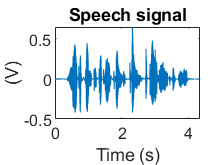

%--------------------------------------------------------------------------------------------
% Create a random vector with Gaussian distributuion, use the standard
% deviation you calculated before (Note: STD = sqrt(noise_power) ). 
% Apply proper FIR filters to the white noise, to obtain pink and blue noises. 
% Add those to the original signal. 
% Plot and save the result.
%-------------------------------------------------------------------------------------------

%Generate white Gaussian noise
white_noise = ...

%Generate pink noise (cut-off frequency fc=1kHz, filter order N=75)
a = 1; 
b = fir1(75,1000/(fs/2),'low'); 
pink_noise = filter(...


%Generate blue noise (use a cut-off frequency of fc=3kHz and a filter order of N=50)
... 
 
%Add noise to the signal
x_white = ...
x_pink = ...
x_blue = ...

% Represent the noisy signals  
...

%Listen to the noisy signals 
...

**ANSWER** (comment on what you heard)

## **Assignment 2: Vowel and formants analysis - Non-parametric spectral estimation**

We can analyse a vowel sound in the frequency domain as comprising harmonics of fundamentals (which are the resonance frequencies of the phonation).

Each resonating frequency of the vocal tract is known as “formant”. Inferring the formants allows recognizing the vowel. 

In a real-life scenario, it would first be necessary to manipulate the signal, to clean it of noise and then isolate the individual phonemes. These techniques are used for speech synthesis algorithms and to help people whose hearing is damaged to interpret words and languages. 

In the case of this lab, the aim is to recognise a clean synthesised vowel by observing its fundamental frequencies. Formally, each vowel is characterized by four formants, but in our case, formants 1 and 2 bring sufficient information to identify the vowel using this graph. 

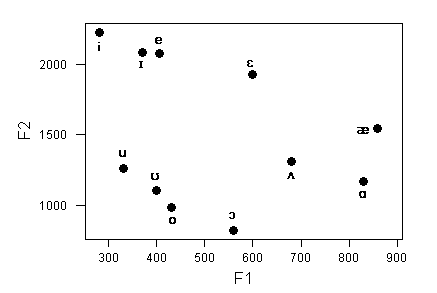

Since the sound we are going to analyze sound has been artificially generated, we know for sure that it is a stationary signal (WSS). Therefore, it is possible to analyse it respecting Wiener–Khintchine’s theorem. 

Despite of this, the choice of window length used to extract the power spectral density of the signal remains critical. The window should cover a glottal source (vibration waveform that excites the vocal cords to produce the speech sound). If the window is shorter, the spectrogram will be unable to resolve the harmonic of each glottal source, and we will obtain a resolution too low for identifying the formants. 

With a too long a window, spectral leakage will occur, and formants will be no longer the highest peaks of power spectral density.

**QUESTION 2a**

Load the two .wav files containing the synthesized vowels and plot their time course. You will notice that through this representation, there is no way to recognize which vowels they are. The sampling frequency is 44 kHz. 

%------------------------------------------------------------------------------------------
% Load the .wav files and plot the signals against time using a subplot
% ---------------------------------------------------------------------------------------

fs = 44000; %44 KHz

% Your code goes here (5-7 lines)

**QUESTION 2b**

Extract the power spectral density (PSD) of the two signals. Remember that, when applied to sound signals, it is customary to scale the spectrogram magnitude logarithmically, as a decibel scale.

You can use the non-parametric method you prefer. To do so, use different types of window and different window lengths:

- Rectangular window of length 3, 40, and 600 ms

- Hanning window of length 3, 40 and 600 ms

Observe and discuss the result.

Check out [this web page](https://nl.mathworks.com/help/signal/ug/windows.html) to learn about all the windows that can be created using MATLAB.

Non-parametric spectral estimation method you can use are: 

- Periodogram (see [*periodogram*](https://nl.mathworks.com/help/signal/ref/periodogram.html) function help page)

- Periodogram wiht Welch's method (see [*pwelch*](https://nl.mathworks.com/help/signal/ref/pwelch.html) function help page)

- Periodogram with Brtlett's method (use Welch's method specifyng an overlap of 0 samples)

%------------------------------------------------------------------------------------------
% Extract the signals power spectral density function, using different window types and window lenghts.
% Plot the results using a subplot (for example you can place spectrograms exctracted with the rectangular windows on the left column, 
% ones extracted with Hanning window on the rigth column)
% Remember to represent the spectrogram in dB --> 20*log10(spectrogram)
% ---------------------------------------------------------------------------------------


close all; clear all; clc
fs = 44000; %44 KHz

[y1,fs] = audioread("vowel1.wav");
[y2,fs] = audioread("vowel2.wav");

figure();
t = (0:length(y1)-1)/fs;
t=linspace(0,length(y1)/fs,length(y1));
plot(t,y1)

%figure();
% periodogram(y1,rectwin(length(y1)),length(y1),fs);
figure();
subplot(3,2,1)
[p1,Fs]= pwelch(y1,rectwin(3e-3*fs),0,256,fs);
plot(Fs,20*log10(p1))
title("F1, Welch's method, Rechtangular window length: 3ms")
xlabel('Frequency (Hz)')
ylabel('Spectrum Magnitude (dB)')
%hold on
%figure();

subplot(3,2,3)
[p2,Fs]= pwelch(y1,rectwin(40e-3*fs),0,256,fs);
plot(Fs,20*log10(p2))
title("Y1 Welch's method Rechtangular window length: 40ms")
xlabel('Frequency (Hz)')
ylabel('Spectrum Magnitude (dB)')
%hold on

subplot(3,2,5)
%figure();
[p3,Fs]= pwelch(y1,rectwin(600e-3*fs),0,256,fs);
plot(Fs,20*log10(p3))
title("Y1 Welch's method Rechtangular window length: 600ms")
xlabel('Frequency (Hz)')
ylabel('Spectrum Magnitude (dB)')

subplot(3,2,2)
[p4,Fs]= pwelch(y2,rectwin(3e-3*fs),0,256,fs);
plot(Fs,20*log10(p4))
title("Y1 Welch's method Rechtangular window length: 3ms")
xlabel('Frequency (Hz)')
ylabel('Spectrum Magnitude (dB)')
%hold on
%figure();

subplot(3,2,4)
[p5,Fs]= pwelch(y2,rectwin(40e-3*fs),0,256,fs);
plot(Fs,20*log10(p5))
title(" Welch's method Rechtangular window length: 40ms")
xlabel('Frequency (Hz)')
ylabel('Spectrum Magnitude (dB)')
%hold on

subplot(3,2,6)
%figure();
[p6,Fs]= pwelch(y2,rectwin(600e-3*fs),0,256,fs);
plot(Fs,20*log10(p6))
title("F2, Welch's method Rechtangular window length: 600ms")
xlabel('Frequency (Hz)')
ylabel('Spectrum Magnitude (dB)')

%%


**DISCUSSION **

Which window allows you to recognize the formant better? Why? Do you notice any difference between the two analyzed vowels?

**ANSWER**

**QUESTION 2c**

Using the graph above, can you recognize the two vowels? If you cannot confidently distinguish the two formants, try different window types, different lengths, or different nonparametric methods for extracting spectral information. 

HINT: if you identify more than two peaks, if you identify more than two peaks, consider only the first two, associated with lower frequencies.

**ANSWER **(write here wich vowels you identified)

## Assignment 3: Vowel formants analysis - Parametric spectral estimation 

Let us now try to identify vowel formants by parametric spectral estimation. 

In general, the vocal tract could be reasonably approximated in terms of a rational transfer function represented by poles and zeros, the poles corresponding to vocal tract resonances, and the zeros to such effects as coarticulation and coupling between the vocal tract and the nasal cavity. As we are dealing with vowels (sounds produced by a vocal tract resonation) an AR model will be sufficient to estimate the spectral density of our signals. 

For this purpose, we will use a linear predictor. Matlab provides the function *lpc*, which estimates the coefficients of a linear predictor FIR Wiener filter. The Wiener filter with these coefficients will predict each value of the signal based on past samples. 

What we have to give it as input is the model order, the choice of which can greatly influence the final result.

Before starting the assignment, read the help of function “*lpc*”.

**QUESTION 3a**

There are several criteria that can help us to choose the best model: 

- Residual error, ${\hat{\sigma} }^2$ which is the variance of the residual signal $\hat{x} -x$. The best model will present the lowest variance. 

- Coefficient of determination, $R^2 =1-\frac{{\hat{\sigma} }^2 }{{\sigma_x }^2 }$, which is 1 minus the ratio between the residual error and the variance of the signal. The best model will present the highest coefficient of determination. 

- Final predictor error, $\textrm{FPE}=\frac{N+P}{N-P}\;{\hat{\sigma} }^2$, where N is the number of sample of the signal, P is the filter order. The best model is chosen as the one that yields the lowest FPE.

- Akaike's information criterion, $\textrm{AICc}=N\cdot \ln \left({\hat{\sigma} }^2 \right)+2P+\frac{2P\left(P+1\right)}{N-P-1}$. Once again the best model is chosen as the one associated with le lowest AICc. 

To calculate all of this indexes you will need the variance of the prediction error (residual error), returned by the MATLAB function “lpc”. 

In practice, it is not possible to indiscriminately increase the filter order. Therefore, using one or more of these criteria, we select the order associated the best parameter value. 

Which of these criteria may be useful in choosing the model order and which not? Explain why. 

**ANSWER**: 

FPE and AIC are appropriate choices for choosing the model order. The reason for the is that only in these two, the criteria is dependent on P, which is the model size. The other criteria are not dependent on the model parameters. This would result in an overfitted model. 

**QUESTION 3b**

In consistency with your answer 3a, choose **one** suitable criterion for choosing the model order. Calculate its value for increasing model orders (form 100 to 400). Then individuate the model order associated to the best value of the chosen criterion. 

Repeat this process for both the vowel signals.

%------------------------------------------------------------------------------------------
% Using a loop, extract two criteria value for a range of orders. Remember
% thatr you need the residual error, wich is an output of lpc function. 
% Identify the best obtained value for each chosen criterion and calculate the threshold of
% aceptance as: 
% threshold = best_value +/- 7/100 * (max(criteria)-min(criteria))
% Using a plot, represent the criteria value against model orders and
% superimpose the found threshold. Identify the lowest model order
% associated with a criteria value below (or above in case of criterion 2)
% the threshold
% ---------------------------------------------------------------------------------------

close all; clear all; clc;
%fs = 44000; %44 KHz

[y2,fs2] = audioread("vowel2.wav");
[y1,fs1] = audioread("vowel1.wav");

 model_orders = [100:400];

 var1 = zeros(length(model_orders),1);
 FPE1 = zeros(length(model_orders),1);
 AICc1 = zeros(length(model_orders),1);

 var2 = zeros(length(model_orders),1);
 FPE2 = zeros(length(model_orders),1);
 AICc2 = zeros(length(model_orders),1);

 % Vowel 1
 idx = 1;
 for modelOrder=100:400
     %Extract two criteria value (3-4 lines of code)
    [output1,var_curr_length] = lpc(y1,modelOrder);
    var1(idx)= var_curr_length;
     FPE1(idx) = var_curr_length*(fs1+idx)/(fs1-(idx));
     AICc1(idx) = fs1*(log(var_curr_length)) + 2*(idx) + (2*idx)*(idx+1)/(fs1-(idx)-1);

    [output2,var_curr_length] = lpc(y2,modelOrder);
    var2(idx)= var_curr_length;
     FPE2(idx) = var_curr_length*(fs2+idx)/(fs2-(idx));
     AICc2(idx) = fs2*(log(var_curr_length)) + 2*(idx) + (2*idx)*(idx+1)/(fs2-(idx)-1);
     idx=idx + 1;
 end

figure();
subplot(2,2,1)
plot(model_orders,FPE1)
[Ma,Ia] = min(FPE1);
tMin = model_orders(Ia);
xline(tMin, 'Color', 'r', 'LineWidth', 2)
textLabel = sprintf(' Min of %.2f at t=%f', Ma, tMin);
text(tMin, Ma, textLabel, 'fontSize', 8, 'Color', 'r', 'VerticalAlignment','bottom')
title('FPE Y1');
xline(tMin, 'Color', 'r', 'LineWidth', 2)
xlabel('Model Order')
ylabel('Variance')
legend('AR estimation ')

subplot(2,2,2)
plot(model_orders,AICc1)
[M,I] = min(AICc1);
tMin = model_orders(I);
xline(tMin, 'Color', 'r', 'LineWidth', 2)
textLabel = sprintf(' Min of %.2f at t=%f', M, tMin);
text(tMin, M, textLabel, 'fontSize', 8, 'Color', 'r', 'VerticalAlignment','bottom')
title('AIC Y1');
xlabel('Model Order')
ylabel('Variance')
legend('AR estimation ')


subplot(2,2,3)
plot(model_orders,FPE2)
[Ma,Ia] = min(FPE2);
tMin = model_orders(Ia);
xline(tMin, 'Color', 'r', 'LineWidth', 2)
textLabel = sprintf(' Min of %.2f at t=%f', Ma, tMin);
text(tMin, Ma, textLabel, 'fontSize', 8, 'Color', 'r', 'VerticalAlignment','bottom')
title('FPE Y2');
xline(tMin, 'Color', 'r', 'LineWidth', 2)
xlabel('Model Order')
ylabel('Variance')
legend('AR estimation ')

subplot(2,2,4)
plot(model_orders,AICc2)
[M,I] = min(AICc2);
tMin = model_orders(I);
xline(tMin, 'Color', 'r', 'LineWidth', 2)
textLabel = sprintf(' Min of %.2f at t=%f', M, tMin);
text(tMin, M, textLabel, 'fontSize', 8, 'Color', 'r', 'VerticalAlignment','bottom')
title('AIC Y2');
xlabel('Model Order')
ylabel('Variance')
legend('AR estimation ')

**QUESTION 3c**

Use the selected order as input and extract the coefficients  $a_i$ of the FIR filter using the *lpc* function. 

The magnitude frequency response of the filter will represent the spectral estimation of the signal. You can plot it using the MATLAB function “*freqz*” specifying no output. 

NOTE: *lpc* function will only calculate $a_i$ coefficeint. As we are dealing with an AR model (all poles), we will have only one *b* coefficient and it is going to be *b=1*. 

Repeat this process for both the vowel signals. Can you recognize the same formants as before?

%------------------------------------------------------------------------------------------
% Select the minimum order that is associated with an acceptable criteria value. 
% Use it as an input of lpc function and extract the filter coefficients.
% Use freqz to represent the frequency fresponce of the obtained model. 
% ---------------------------------------------------------------------------------------


close all; clear all; clc

[y1,fs] = audioread("vowel1.wav");
[y2,fs] = audioread("vowel2.wav");

 [output1,var_curr_length1] = lpc(y1,145);
 [output2,var_curr_length2] = lpc(y2,145);

 figure(1);
 subplot(2,2,1)
[h1, fs1] = freqz(1,output1,10,fs);
plot(fs1, mag2db(abs(h1)))
title("Y1 With b = 10")
xlabel('Frequency')
ylabel('Magnitude db')

subplot(2,2,2)
[h1, fs1] = freqz(1,output1,22000,fs);
plot(fs1, mag2db(abs(h1)))
title("Y1 With b = 22,000")
xlabel('Frequency')
ylabel('Magnitude db')

subplot(2,2,3)
[h2, fs2] = freqz(1,output2,10,fs);
plot(fs2, mag2db(abs(h2)))
title("Y2 With b = 10")
xlabel('Frequency')
ylabel('Magnitude db')

subplot(2,2,4)
[h2, fs2] = freqz(1,output2,22000,fs);
plot(fs2, mag2db(abs(h2)))
title("Y2 With b = 22,000")
xlabel('Frequency')
ylabel('Magnitude db')

**ANSWER**

## Assignment 4 - Solution: Constant False Alarm Rate (CFAR) detection in Doppler radar 

### Introduction 

Note: you are only suggested to read the first two parts if you would like to know more about Dopper radar, otherwise you can directly start with reading *3) Constant False Alarm Rate (CFAR) detection.*

#### 1) Radar

In its most basic form, a radar transmits an electromagnetic pulse, and if a target is present within a certain angle and range, it will receive an echo, as shown in Fig. 1.

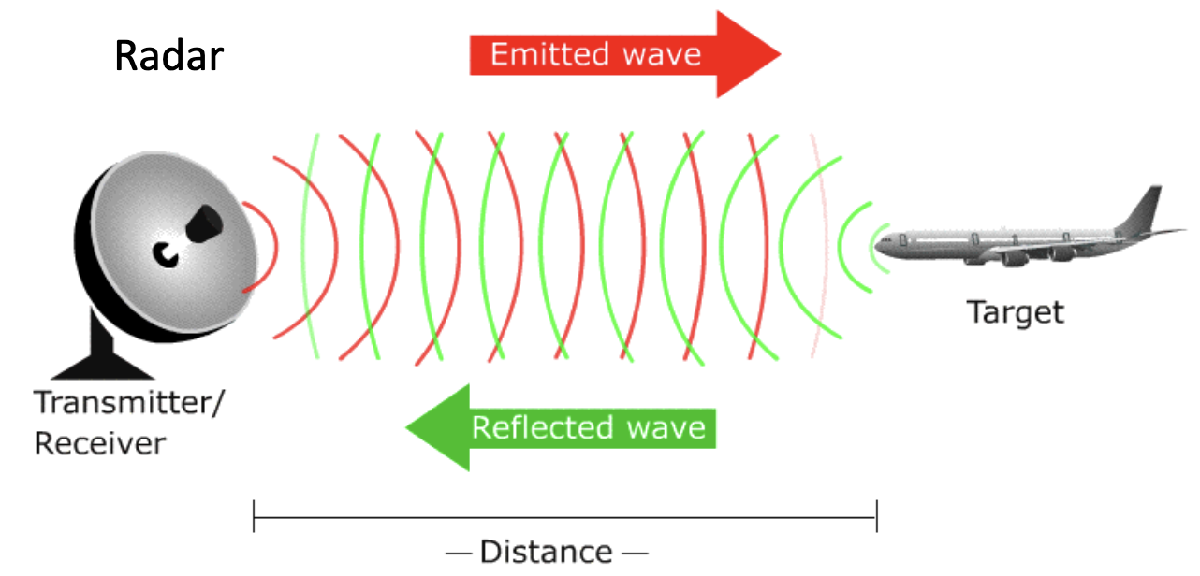

Fig. 1: Principle of a radar.

The task at hand at the receiver is to decide if a target is present at a particular range. Therefore, it creates a so-called range map, obtained by sampling the received signal after some processing. An example of a range map can be seen in Fig. 2.

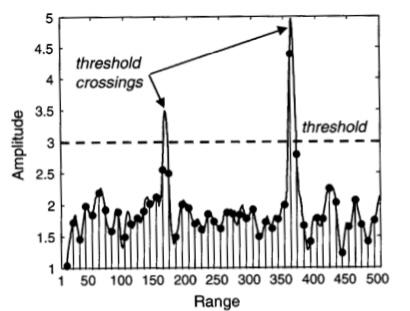

Fig. 2: Example of a range map

#### 2) Doppler effect and Doppler radars

The Doppler effect describes the difference between the observed frequency and the emitted frequency of a wave when the source moves relative to the observer. The received frequency is higher when the source moves towards you and lower when moving away. For example, the pitch will be high if an ambulance's siren drives toward you. Conversely, you will hear the pitch suddenly drop when it goes past you and drives away. Both effects are indicated in Fig. 3.

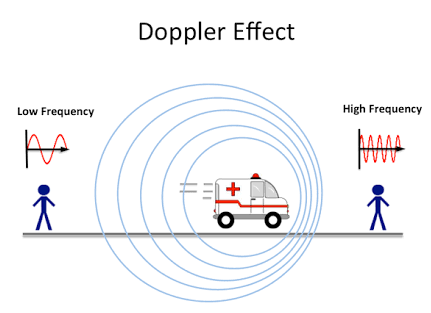

Fig 3. Example of the Doppler effect 

A Doppler radar is a special radar that utilizes the Doppler effect to produce velocity data about objects at a distance. Regular radars send out pulses of radio waves and detect the returned pulses. The time difference between the transmission and reception of a pulse is used to determine an object's range (distance). In addition, Doppler radars look at the phase change of the received pulse due to the Doppler effect. In this way, Doppler radars can also determine the velocity of objects. The range map is thereby extented by the Doppler dimesnion, resulting in a range-Doppler map.  This video could help you understand more in detail: [https://www.youtube.com/watch?v=NtyU6aKZ-cY](https://www.youtube.com/watch?v=NtyU6aKZ-cY) 

#### 3) Constant False Alarm Rate (CFAR) detection 

The detection efficiency of a radar is characterized by the probability of detection $P_d$ and the  probability of false alarm $P_{\textrm{fa}}$. According to the Neyman-Pearson criterion, the optimal detector of a radar target signal against noise should maximize $P_d$ for a given $P_{\textrm{fa}}$. 

In general, the signal strength of the echo is unknown, and thus, we cannot define the probability of detection${\;P}_d$. However, if we assume we know the statistics of the noise created by the receiver hardware, we can calculate $P_{\textrm{fa}}$. For a $P_{\textrm{fa}}$, we can define a thrershold $Z_T$, and the presence of the target is declared whenever the signal exceeds the threshold, as shown in Fig. 2.

In many practical scenarios, the noise statistic is not known as a priori and may vary temporally and spatially. Moreover, echoing objects may not be located in front of a clear or empty background. Instead, there will be clutter presesent in the received signal. In such situations, a detector designed to adapt its threshold is advantageous. In other words, the threshold level is raised and lowered to maintain a constant probability of false alarm. This is known as CFAR detection. 

#### 4) Basic1D CFAR architecture 

The basic 1D CFAR architecture is shown in Fig 4. The CFAR window comprises a leading and a lagging window, guard cells, and a cell under test (CUT). The CUT is located in the center of the CFAR window. The term CUT refers to the current cell to which the CFAR threshold is to be applied. Measurements contained in the guard cells are not used to estimate the interference statistics, as they may contain returns associated with the target in the CUT, which will bias the interference estimate. 

The CFAR window is moved through the data window one sample or cell at a time. At each position, a detection decision is made regarding the measurement in the CUT. The detection threshold applied to the CUT is derived from measurements in the leading and lagging window (also called training cells). The threshold is calculated as:

 $Z_{{\;}_T } =\alpha \;\hat{g}$,

where the CFAR constant $\alpha \;$ is a function of the desired $P_{\textrm{fa}}$. $\hat{g}$ is the estimated statistics from the leading and lagging windows which makes the threshold adaptive. 

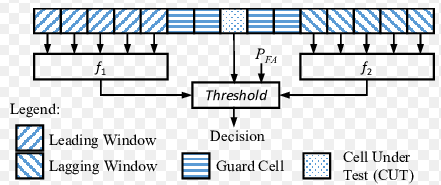

Fig 4. Basic 1D CFAR architecture 

### Visualize a real-life dataset 

**QUESTION 4a **

- Load the dataset "radar.mat". This is one of the real-life datasets measured on the A13 highway by the PARSAX Radar (Fig. 5). The measurment setup is shown in Fig. 6. The **Data_out **matrix contains 30208 consecutive range measurements. Each range measurement comprises 270 range bins. The correspondoing range values are provided in the **range** vector. The consecutive measurements are obtained by transmitting a radar signal ever milisecond (variable **Ts**). The time axis for the consecutive measurements is referred to as slow time. 

             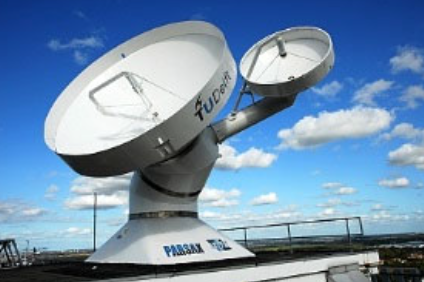   

            Fig 5. PARSAX S-band Doppler radar from TU Delft 

          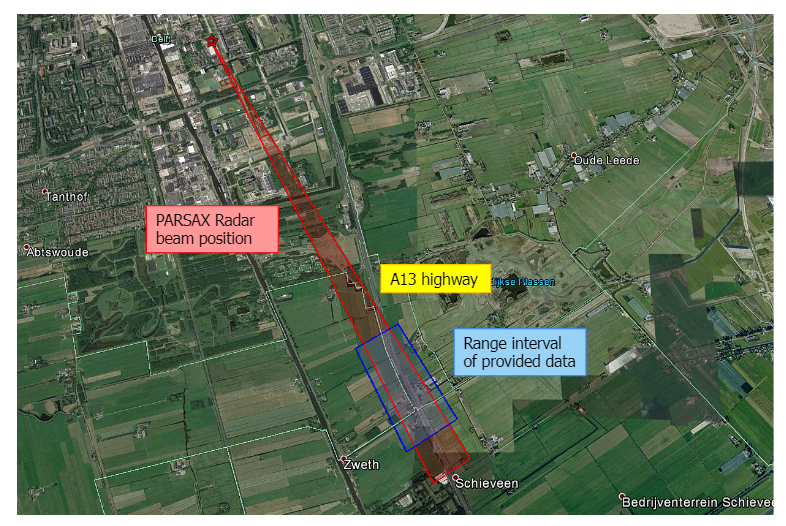

            Fig 6. Measurement setup 

% === 1. LOAD DATASET ===
% write code to load radar.mat here 

**QUESTION 4b**

Use ***imagesc*** to visualize the magnitude of the **Data_out** in **dB** with respect to slow-time and range, don't forget to label axes.

% === 2. PLOT === 
Ts = 1e-3; % -- given, sampling time interval 
slow_time = (1:size(Data_out)*Ts); % -- given 

% make you plot here with imagesc 

**QUESTION 4c**

Use the discrete Fourier transform along the slow-time to create the range-Doppler map (RDM). Therefore, we consider the first 512 measurements (defined in the variable N_doppler). Plot the magnitude in **dB** and make sure your zero Doppler frequency is in the center. 

% === 3. RDM === 
N_doppler = 512; % -- this line is given 
freq = (-500:1000/(N_doppler+1):500);  % -- this line is given

% make your plot here 

**QUESTION 4d**

In the RDM, you will see a vertical line at zero doppler frequency across all ranges, this line represents stationary objects present at all ranges. Also, you will see objects at positive and negative frequencies, can you explain what do they represent?

**ANSWER**

## Assignment 5: 1D CFAR detection 

In this assignment, we will apply CFAR to the above dataset. We will investigate only the 1D case. Therefore, we consider the range map from a single range measurement. Follow the instructions and finish the required code to get the first impression of the adaptive thehold in CFAR. 

**QUESTION 5a**

Plot the power (square of magnitude) of the selected data with range, dont forget axes lables.  

% select one row data 
data = Data_out(40,:)'; % given

% compute the square of magnitude of the data and plot it with respect to range, don't forget axes labels 
p_data = %*******% finish the code to compute the square of magnitude of the data, dont change the variable name p_data

**QUESTION 5b **

We design a 1D CFAR. Assuming the desired  $P_{\textrm{fa}} =$${10}^{-4}$, number of leading and lagging windows (defined as numTrainingCell in Matlab) are 200, fill in those parameters below at the right places.  

cfar = phased.CFARDetector('NumTrainingCells',20,'NumGuardCells',2);

exp_pfa =  %*******% fill in the desired Pfa here 
cfar.ThresholdFactor = 'Auto';
cfar.ProbabilityFalseAlarm = exp_pfa;
release(cfar);
cfar.ThresholdOutputPort = true;
cfar.ThresholdFactor = 'Auto';
cfar.NumTrainingCells = %*******% fill in the number of leading and lagging widnows here 

        Now we apply CFAR on the data

[x_detected,th] = cfar(p_data,1:length(p_data));

**QUESTION 5c**

Plot signals, threhold, and detections 

figure;
plot(1:length(p_data),%*******% ); % finish this line to plot p_data
hold on 
plot(1:length(p_data), %*******% ); % finish this line to plot the variable th 
plot(find(x_detected),p_data(x_detected),'o')
legend('Signal','Threshold','Detections','Location','Northwest')
xlabel('Time Index')
ylabel('Level')

**QUESTION 5d**

Change the number of leading and lagging windows to 20, keep the desired  $P_{\textrm{fa}} ={10}^{-4}$, make the plot in the last question again, which window size you find better, 20 or 200?

cfar = phased.CFARDetector('NumGuardCells',2);

exp_pfa =  %*******% fill in the desired Pfa here 
cfar.ThresholdFactor = 'Auto';
cfar.ProbabilityFalseAlarm = exp_pfa;
release(cfar);
cfar.ThresholdOutputPort = true;
cfar.ThresholdFactor = 'Auto';

cfar.NumTrainingCells = %*******%; % fill in the number of leading and lagging widnows here 
[x_detected,th] = cfar(p_data,1:length(p_data));

figure;
plot(1:length(p_data),%*******% ); % finish this line to plot p_data
hold on 
plot(1:length(p_data), %*******% ); % finish this line to plot the variable th 
plot(find(x_detected),p_data(x_detected),'o')
legend('Signal','Threshold','Detections','Location','Northwest')
xlabel('Time Index')
ylabel('Level')

Which window size do you find better, 20 or 200? Explain your answer to this question.

**ANSWER**

## References

O. A. Krasnov, L. P. Ligthart, Zhijian Li, P. Lys and F. van der Zwan,  "The PARSAX - full polarimetric FMCW radar with dual-orthogonal  signals," *2008 European Radar Conference*, 2008, pp. 84-87